Part 1: creating first look up table

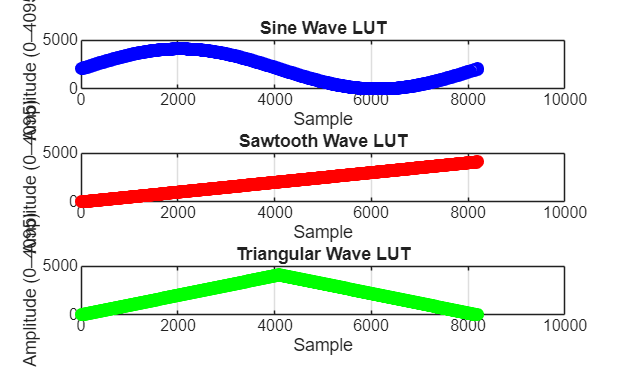

% Task 1 Part 1 - Generate LUTs for waveforms (12-bit, 128 samples)
NS = 8192;                 % Number of samples
n = 0:NS-1;               % Sample indices
maxVal = 4095;            % 12-bit max

% ----- Sine LUT -----
sineLUT = round((maxVal/2) * (sin(2*pi*n/NS) + 1));

% ----- Sawtooth LUT -----
sawLUT = round((maxVal/NS) * n);

% ----- Triangular LUT -----
triLUT = round((2*maxVal/NS) * n);
triLUT(triLUT > maxVal) = 2*maxVal - triLUT(triLUT > maxVal);

% ----- Plot the results -----
figure;

subplot(3,1,1);
plot(n, sineLUT, 'b-o'); grid on;
title('Sine Wave LUT');
xlabel('Sample'); ylabel('Amplitude (0–4095)');

subplot(3,1,2);
plot(n, sawLUT, 'r-o'); grid on;
title('Sawtooth Wave LUT');
xlabel('Sample'); ylabel('Amplitude (0–4095)');

subplot(3,1,3);
plot(n, triLUT, 'g-o'); grid on;
title('Triangular Wave LUT');
xlabel('Sample'); ylabel('Amplitude (0–4095)');


% ===== Export to C arrays =====
% Function to print as uint16_t C array
printCarray = @(name, arr) fprintf('uint16_t %s[%d] = { %s };\n\n', ...
                                   name, length(arr), ...
                                   sprintf('%d, ', arr(1:end-1)) + "" + arr(end));

fprintf('--- C Arrays ---\n\n');

--- C Arrays ---



printCarray('sineLUT', sineLUT);

uint16_t sineLUT[8192] = { 2048, 2049, 2051, 2052, 2054, 2055, 2057, 2058, 2060, 2062, 2063, 2065, 2066, 2068, 2069, 2071, 2073, 2074, 2076, 2077, 2079, 2080, 2082, 2084, 2085, 2087, 2088, 2090, 2091, 2093, 2095, 2096, 2098, 2099, 2101, 2102, 2104, 2106, 2107, 2109, 2110, 2112, 2113, 2115, 2117, 2118, 2120, 2121, 2123, 2124, 2126, 2128, 2129, 2131, 2132, 2134, 2135, 2137, 2139, 2140, 2142, 2143, 2145, 2146, 2148, 2150, 2151, 2153, 2154, 2156, 2157, 2159, 2161, 2162, 2164, 2165, 2167, 2168, 2170, 2171, 2173, 2175, 2176, 2178, 2179, 2181, 2182, 2184, 2186, 2187, 2189, 2190, 2192, 2193, 2195, 2197, 2198, 2200, 2201, 2203, 2204, 2206, 2208, 2209, 2211, 2212, 2214, 2215, 2217, 2218, 2220, 2222, 2223, 2225, 2226, 2228, 2229, 2231, 2233, 2234, 2236, 2237, 2239, 2240, 2242, 2244, 2245, 2247, 2248, 2250, 2251, 2253, 2254, 2256, 2258, 2259, 2261, 2262, 2264, 2265, 2267, 2268, 2270, 2272, 2273, 2275, 2276, 2278, 2279, 2281, 2283, 2284, 2286, 2287, 2289, 2290, 2292, 2293, 2295, 2297, 2298, 2300, 2

printCarray('sawLUT', sawLUT);

uint16_t sawLUT[8192] = { 0, 0, 1, 1, 2, 2, 3, 3, 4, 4, 5, 5, 6, 6, 7, 7, 8, 8, 9, 9, 10, 10, 11, 11, 12, 12, 13, 13, 14, 14, 15, 15, 16, 16, 17, 17, 18, 18, 19, 19, 20, 20, 21, 21, 22, 22, 23, 23, 24, 24, 25, 25, 26, 26, 27, 27, 28, 28, 29, 29, 30, 30, 31, 31, 32, 32, 33, 33, 34, 34, 35, 35, 36, 36, 37, 37, 38, 38, 39, 39, 40, 40, 41, 41, 42, 42, 43, 43, 44, 44, 45, 45, 46, 46, 47, 47, 48, 48, 49, 49, 50, 50, 51, 51, 52, 52, 53, 53, 54, 54, 55, 55, 56, 56, 57, 57, 58, 58, 59, 59, 60, 60, 61, 61, 62, 62, 63, 63, 64, 64, 65, 65, 66, 66, 67, 67, 68, 68, 69, 69, 70, 70, 71, 71, 72, 72, 73, 73, 74, 74, 75, 75, 76, 76, 77, 77, 78, 78, 79, 79, 80, 80, 81, 81, 82, 82, 83, 83, 84, 84, 85, 85, 86, 86, 87, 87, 88, 88, 89, 89, 90, 90, 91, 91, 92, 92, 93, 93, 94, 94, 95, 95, 96, 96, 97, 97, 98, 98, 99, 99, 100, 100, 101, 101, 102, 102, 103, 103, 104, 104, 105, 105, 106, 106, 107, 107, 108, 108, 109, 109, 110, 110, 111, 111, 112, 112, 113, 113, 114, 114, 115, 115, 116, 116, 117, 117, 118, 118, 119,

printCarray('triLUT', triLUT);

uint16_t triLUT[8192] = { 0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41, 42, 43, 44, 45, 46, 47, 48, 49, 50, 51, 52, 53, 54, 55, 56, 57, 58, 59, 60, 61, 62, 63, 64, 65, 66, 67, 68, 69, 70, 71, 72, 73, 74, 75, 76, 77, 78, 79, 80, 81, 82, 83, 84, 85, 86, 87, 88, 89, 90, 91, 92, 93, 94, 95, 96, 97, 98, 99, 100, 101, 102, 103, 104, 105, 106, 107, 108, 109, 110, 111, 112, 113, 114, 115, 116, 117, 118, 119, 120, 121, 122, 123, 124, 125, 126, 127, 128, 129, 130, 131, 132, 133, 134, 135, 136, 137, 138, 139, 140, 141, 142, 143, 144, 145, 146, 147, 148, 149, 150, 151, 152, 153, 154, 155, 156, 157, 158, 159, 160, 161, 162, 163, 164, 165, 166, 167, 168, 169, 170, 171, 172, 173, 174, 175, 176, 177, 178, 179, 180, 181, 182, 183, 184, 185, 186, 187, 188, 189, 190, 191, 192, 193, 194, 195, 196, 197, 198, 199, 200, 201, 202, 203, 204, 205, 206, 207, 208, 209, 210, 211, 212, 213, 214, 215, 216,

Part 2: reading the .wav files

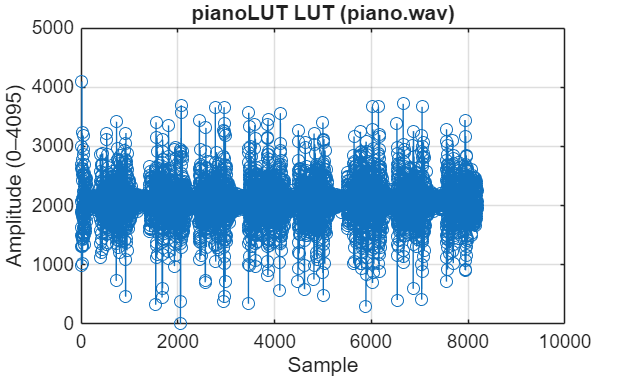

uint16_t pianoLUT[8192] = {


2069, 2069, 2069, 2069, 2069, 2069, 2068, 2069, 2069, 2071, 2068, 1882,  994, 1622, 3004, 2700, 1309, 1500, 2630, 4095, 1898, 1428, 1808, 3228, 2103, 2121, 1459, 1968, 1330, 2517, 1911, 1316, 1014, 2431, 2626, 1977, 1429, 1867, 2597, 2782, 2421, 1501, 2122, 2865, 3183, 1451, 1509, 2174, 2944, 1742, 1608, 1550, 2175, 1860, 2167, 1632, 1606, 1907, 2526, 2233, 1816, 1984, 2262, 2547, 2412, 2211, 1696, 2330, 2695, 2510, 1341, 1771, 2364, 2492, 1514, 1611, 1894, 2152, 1800, 1926, 1828, 2040, 2206, 2210, 2012, 2085, 2463, 2235, 2202, 2192, 2358, 1909, 2205, 2216, 2146, 1567, 2016, 2103, 2024, 1608, 1910, 2002, 2113, 1979, 1985, 1965, 2188, 2372, 2102, 2029, 2192, 2457, 2072, 2088, 2103, 2247, 1896, 2133, 2051, 2011, 1736, 2064, 2075, 2008, 1839, 2009, 2093, 2146, 2090, 1994, 2070, 2195, 2299, 2008, 2046, 2135, 2295, 1970, 2047, 2041, 2139, 1923, 2113, 2000, 2022, 1922, 2152, 2043, 2025, 2009, 2109, 2103, 2118, 2096, 2002, 2102, 2168, 2159, 1927, 2071, 2143, 2161, 1910, 2046, 2064, 2120, 1948

};



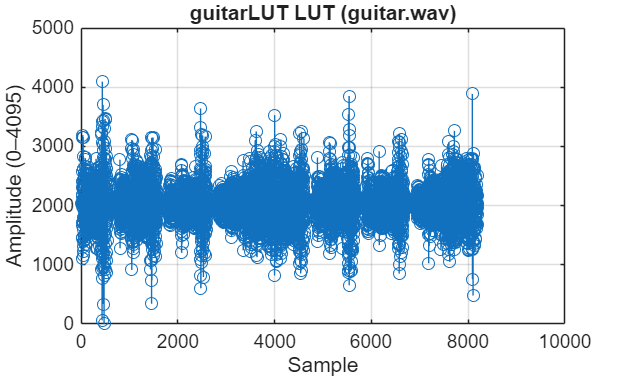

uint16_t guitarLUT[8192] = {


2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2029, 2028, 2027, 2029, 1995, 2075, 2036, 2079, 2032, 1982, 2034, 2156, 2043, 1719, 2195, 2408, 2572, 1112, 1667, 2300, 3190, 1436, 1468, 2054, 3145, 1720, 1160, 1735, 3158, 2296, 1386, 1797, 2822, 2370, 1306, 1704, 2299, 2629, 1592, 2121, 2069, 2434, 1229, 2060, 1950, 2562, 1415, 2156, 2114, 2536, 1491, 1793, 2014, 2469, 1803, 1856, 2295, 2435, 2050, 1420, 2067, 2208, 2444, 1470, 2105, 2052, 2660, 1341, 1878, 1816, 2805, 1693, 1836, 1795, 2777, 1972, 1675, 1734, 2519, 2216, 1710, 1928, 2327, 2422, 1548, 1915, 1970, 2532, 1558, 2132, 1913, 2593, 1450, 2030, 1863, 2604, 1595, 1921, 1974, 2603, 1835, 1738, 1974, 2427, 2056, 1637, 2085, 2345, 2364, 1521, 2035, 1990, 2461, 1508, 2127, 1920, 2572, 1535, 2042, 1872, 2545, 1680, 1912, 1923, 2516, 1938, 1824, 1981, 2308, 2094, 1696, 2071, 2193, 2359, 1627, 2115, 1918, 2414, 1560, 2163, 1890, 2509, 1586, 2079, 1867, 2465, 1700, 1935, 1963, 2429

};



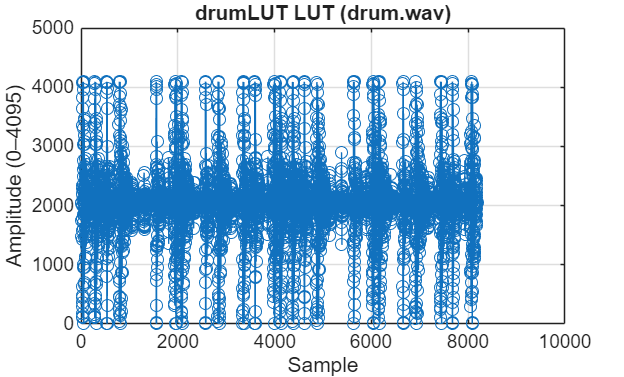

uint16_t drumLUT[8192] = {


2048, 2048, 2048, 2048, 2047, 2047, 2046, 2049, 2050, 2049, 2044, 2046, 2050, 2044, 2044, 2043, 2045, 2042, 2049, 1475, 1745, 1584, 2291, 2189,  624, 3357, 2340,  108,  116, 3818, 3636,  169,  359, 4086, 4086, 1779,  480, 1993, 2211,  288,  439, 1428, 1614, 1842, 1711, 2055, 3032, 3954, 4092, 4083, 3305, 2762, 2247, 2348,  953,    5,    0,    5, 1001, 2109, 2613, 2499, 2653, 3030, 3430, 3192, 3184, 3473, 3085, 1948,  705,  667,  961, 1458, 1875, 2274, 2302, 2023, 1827, 2095, 2291, 2138, 2180, 2326, 2433, 2259, 2167, 2176, 2136, 1949, 1613, 1135, 1098, 1472, 1855, 2046, 2296, 2602, 2796, 2651, 2423, 2406, 2524, 2493, 2163, 1831, 1639, 1469, 1306, 1367, 1595, 1808, 1933, 2175, 2495, 2693, 2615, 2406, 2221, 2070, 1919, 1841, 1873, 1915, 1985, 2097, 2104, 1997, 1894, 1885, 1906, 1892, 1915, 1987, 2034, 2097, 2246, 2413, 2481, 2417, 2369, 2262, 1922, 1716, 1568, 1473, 1533, 1759, 1945, 2087, 2328, 2432, 2448, 2405, 2388, 2326, 2162, 1934, 1744, 1674, 1680, 1767, 1924, 2097, 2227, 2252, 2224

};



% Task 1 Part 2 - Generate LUTs from multiple .wav files
% ------------------------------------------------------

% List of wav files (replace with actual names)
wavFiles = {"piano.wav", "guitar.wav", "drum.wav"};
lutNames = {"pianoLUT", "guitarLUT", "drumLUT"};

NS = 8192;       % Number of LUT samples
maxVal = 4095;  % 12-bit max

for k = 1:length(wavFiles)
    % --- Load audio ---
    [signal, fs] = audioread(wavFiles{k});
    signal = mean(signal, 2);  % Convert stereo to mono
    
    % --- Resample to NS samples ---
    NS = 8192; 
    L = length(signal);
    
    % Define new sample positions (128 evenly spaced points)
    x_old = linspace(0, 1, L);
    x_new = linspace(0, 1, NS);
    
    % Resample using interpolation
    signal_resampled = interp1(x_old, signal, x_new, 'linear');

    % --- Normalize 0 to 1 ---
    signal_norm = (signal_resampled - min(signal_resampled)) ./ ...
                  (max(signal_resampled) - min(signal_resampled));
    
    % --- Scale to 12-bit ---
    LUT = round(signal_norm * maxVal);
    
    % --- Plot ---
    figure;
    plot(0:NS-1, LUT, 'o-'); grid on;
    title(sprintf('%s LUT (%s)', lutNames{k}, wavFiles{k}));
    xlabel('Sample'); ylabel('Amplitude (0–4095)');
    
    % --- Export C array ---
    fprintf('uint16_t %s[%d] = {\n', lutNames{k}, length(LUT));
    for i = 1:length(LUT)
        fprintf('%4d, ', LUT(i));
        if mod(i, 16) == 0, fprintf('\n'); end % 16 values per line
    end
    fprintf('};\n\n');
end